# SOAR SeaFET Quality Control Script

Version 1.0 | July 15, 2024

Taylor Wirth - Scripps Institution of Oceanography | twirth@ucsd.edu

User instructions:

- Data file types are csv, with 'comma' delimiter

- Look at example files to ensure the four sensor variable headers are included and the same:

-     DTUTC, VINT, TEMPC (datetime in UTC timezone, internal voltage, temperature in celsius)

- Look at bottle file to ensure four variable headers are included and the same:

-     DT, pH, spectTC, DIC, TA, Sal, QC (datetime local timezone (PST/PDT), pH from spec, temp from spec, ...

-         DIC, TA, salinity from bottle and QC flag)

- Row comments begin with '#'

clc; close all; clear; 

## Step 1: Load sensor data files and bottle files

Select SeaFET and discrete bottle/tris files using the buttons below. 

Provide the folder path for [CO2SYS (v3.1.2)](https://www.mathworks.com/matlabcentral/fileexchange/78378-co2sysv3-for-matlab).

seafet_file = "G:\Shared drives\FET_processing_GUI\SOAR_pH_processing_GUI_Matlab\SOAR Raw - simple format\SIOPier_240201_240417_SIO7JS.csv"; 
data = readtable(seafet_file,'Delimiter',',','CommentStyle','#');
bottle_file = "G:\Shared drives\FET_processing_GUI\SOAR_pH_processing_GUI_Matlab\validation data\SOAR bottle samples.csv";
bott = readtable(bottle_file,'Delimiter',',','CommentStyle','#');
tris_file = "G:\Shared drives\FET_processing_GUI\SOAR_pH_processing_GUI_Matlab\validation data\SOAR tris times.csv";
tris = readtable(tris_file,'Delimiter',',','CommentStyle','#');
co2path = "G:\Shared drives\FET_processing_GUI\SOAR_pH_processing_GUI_Matlab\CO2SYS.m"; % version 3.1.2
addpath(fileparts(co2path));
disp("File start time = ")

File start time = 


disp(string(data.DTUTC(1),'MM/dd/uuuu HH:mm:ss'))

02/01/2024 01:00:00


disp("File end time = ")

File end time = 


disp(string(max(data.DTUTC),'MM/dd/uuuu HH:mm:ss'))

04/17/2024 06:20:00


## Step 2: Enter start and end datetimes (UTC) to trim the deployment (mm/dd/yyyy hh:mm:ss)

Use the fields below to edit the start and end datetimes of the deployment.

A plot of the raw data will open in a separate window. The user can "brush" bad data to NaN if desired.

Leave the figure window open and move on to the next step. The window will automaticall close.

st = datetime("02/01/2024 01:00:00",'InputFormat','MM/dd/uuuu HH:mm:ss');
et = datetime("04/17/2024 06:20:00",'InputFormat','MM/dd/uuuu HH:mm:ss');
disp("Trimmed start time = "+string(st,'MM/dd/uuuu HH:mm:ss'));

Trimmed start time = 02/01/2024 01:00:00


disp("Trimmed end time = "+string(et,'MM/dd/uuuu HH:mm:ss'));

Trimmed end time = 04/17/2024 06:20:00


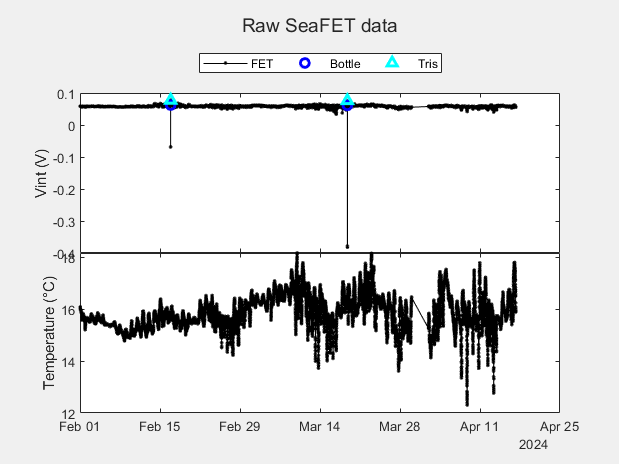

 
% trim each file
trim = data.DTUTC >= st & data.DTUTC <= et;
data = data(trim,:); 
bott = bott(bott.DTUTC >= st & bott.DTUTC <= et,:);
tris = tris(tris.DTUTC >= st & tris.DTUTC <= et,:);

if isempty(tris)==1
    tris = table();
    tris.DTUTC = [NaT;NaT];
    tris.QC = [NaN;NaN];
end
    
close all
fraw = figure('Name','fraw');
tl = tiledlayout(2,1,'TileSpacing','none');
ax1 = nexttile;
plot(data.DTUTC, data.VINT, 'k.-'); hold on
plot(bott.DTUTC, interp1(data.DTUTC, data.VINT, bott.DTUTC,'nearest'),'bo',LineWidth=2);
plot(tris.DTUTC, interp1(data.DTUTC, data.VINT, tris.DTUTC,'nearest'),'c^',LineWidth=2);
ax1.XTickLabel = '';
ax1.YLabel.String = 'Vint (V)';
legend('FET','Bottle','Tris','Location','northoutside','Orientation','horizontal')

ax2 = nexttile;
plot(data.DTUTC, data.TEMPC, 'k.-'); hold on
ax2.YLabel.String = "Temperature ("+char(176)+"C)";
linkaxes([ax1 ax2],'x');

title(tl,'Raw SeaFET data')
set(fraw,'Visible','on')%,'Position',[100 80 1500 800])

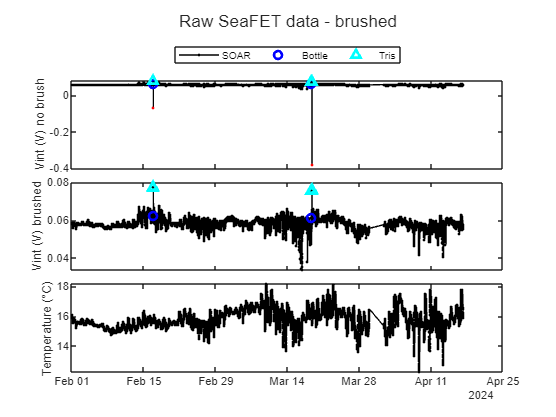

%% collect brushed data
set(fraw,'Position',[ 589   356   560   420])
set(fraw,'Visible','off')
Vint_brushed = ax1.Children(end).YData'; % data with brushed data removed

Vint_prebrushed = data.VINT; % raw data without brushing applied

Vint_brushed; 

intnan = isnan(Vint_brushed); % locations of NaN (brushed) data

 
fraw_brushed = figure; tl = tiledlayout(3,1,'TileSpacing','tight');
ax1 = nexttile;
plot(data.DTUTC, Vint_prebrushed, 'k.-'); hold on
plot(bott.DTUTC, interp1(data.DTUTC, data.VINT, bott.DTUTC,'nearest'),'bo',LineWidth=2);
plot(tris.DTUTC, interp1(data.DTUTC, data.VINT, tris.DTUTC,'nearest'),'c^',LineWidth=2);
plot(data.DTUTC(intnan),Vint_prebrushed(intnan),'r.'); hold on
ax1.XTickLabel = '';
ax1.YLabel.String = 'Vint (V) no brush';
legend('SOAR','Bottle','Tris','Location','northoutside','Orientation','horizontal')

ax2 = nexttile;
plot(data.DTUTC, Vint_brushed, 'k.-'); hold on
plot(bott.DTUTC, interp1(data.DTUTC, data.VINT, bott.DTUTC,'nearest'),'bo',LineWidth=2);
plot(tris.DTUTC, interp1(data.DTUTC, data.VINT, tris.DTUTC,'nearest'),'c^',LineWidth=2);
ax2.XTickLabel = '';
ax2.YLabel.String = 'Vint (V) brushed';

ax3 = nexttile;
plot(data.DTUTC, data.TEMPC, 'k.-'); hold on
ax3.YLabel.String = "Temperature ("+char(176)+"C)";
linkaxes([ax1 ax2 ax3],'x');

title(tl,'Raw SeaFET data - brushed')

 
disp("Number of discrete samples = "+num2str(length(bott.DTUTC)))

Number of discrete samples = 2


bott.TCINSITU = interp1(data.DTUTC, data.TEMPC, bott.DTUTC,'nearest');
bott.VINT = interp1(data.DTUTC, data.VINT, bott.DTUTC, 'nearest');
% calculate in situ pH from discrete bottles w/ TA from bottles
if isempty(bott)==0
    A=CO2SYS(bott.PHSPEC,bott.TA,3,1,bott.SAL,bott.TCSPEC,bott.TCINSITU,0,0,0,0,0,0,1,10,1,2,2);
    bott.PHINSITU = A(:,43); % pH output on the total scale


bott.PHINSITU(bott.PHINSITU == -999) = NaN;
disp(bott(:,1:7))
disp(bott(:,8:end))
end

           DTUTC            PHSPEC    TCSPEC     DIC        TA       SAL      QC
    ____________________    ______    ______    ______    ______    ______    __

    16-Feb-2024 20:40:00    8.0086      20      1981.4    2211.5    33.127    1 
    18-Mar-2024 18:45:00    8.0447      20      1968.4    2212.7    33.269    1 



    TCINSITU      VINT      PHINSITU
    ________    ________    ________

     15.676     0.062377     8.0742 
     16.299     0.061225      8.101 




if all(isnan(tris.QC))
    disp("Number of tris injections = 0")
    tris.TCINSITU = [NaN;NaN];
    tris.VINT = [NaN;NaN];
    tris.PHINSITU = [NaN;NaN];
else
    disp("Number of tris injections = "+num2str(length(tris.DTUTC)))
    tris.TCINSITU = interp1(data.DTUTC, data.TEMPC, tris.DTUTC);
    tris.VINT = interp1(data.DTUTC, data.VINT, tris.DTUTC);
    TC = tris.TCINSITU;
    S = 35;
    TK = TC+273.15;
    pH = (11911.08 - 18.2499.*S - 0.039336.*S^2)./TK... 
    + (-366.27059 + 0.53993607.*S + 0.00016329.*S^2)...
    + (64.52243 - 0.084041.*S).*log(TK) - 0.11149858.*TK;
    tris.PHINSITU = pH;
    disp(tris)
end

Number of tris injections = 7


           DTUTC            QC    TCINSITU      VINT      PHINSITU
    ____________________    __    ________    ________    ________

    16-Feb-2024 20:50:00    2      15.816     0.077229     8.3873 
    16-Feb-2024 20:55:00    1      15.776     0.077365     8.3886 
    16-Feb-2024 21:00:00    1      15.736     0.077686     8.3899 
    18-Mar-2024 18:50:00    2      16.502     0.075748     8.3648 
    18-Mar-2024 18:55:00    1       16.43     0.075907     8.3672 
    18-Mar-2024 19:00:00    1      16.344     0.076026       8.37 
    18-Mar-2024 19:05:00    2      16.316     0.075889     8.3709 



### Apply quality control flags to discrete samples in a nx1 array, where n is the number of samples for each validation method:

Each QC flag is to be bracketed and split by a semicolon. Example: [1; 2; 1; 1; 2; 2]

QC =1 : good

QC = 2 : bad

QC = 3 : questionable

QC = 4: no sensor data

% auto populate QC flags:
str = mat2str(bott.QC);
str = strrep(str, ';', '; ');
disp('Original bottle QC flags:')

Original bottle QC flags:


disp(str)

[1; 1]


str = mat2str(tris.QC);
str = strrep(str, ';', '; ');
disp('Original tris QC flags:')

Original tris QC flags:


disp(str)

[2; 1; 1; 2; 1; 1; 2]


Copy and paste these array outputs into the boxes below to edit QC flags:

if isempty(bott)==0
    bott.QC = [1; 1];
    bottqc = bott(bott.QC==1,:);
    disp(bottqc(:,1:7))
    disp(bottqc(:,8:end))
end

           DTUTC            PHSPEC    TCSPEC     DIC        TA       SAL      QC
    ____________________    ______    ______    ______    ______    ______    __

    16-Feb-2024 20:40:00    8.0086      20      1981.4    2211.5    33.127    1 
    18-Mar-2024 18:45:00    8.0447      20      1968.4    2212.7    33.269    1 



    TCINSITU      VINT      PHINSITU
    ________    ________    ________

     15.676     0.062377     8.0742 
     16.299     0.061225      8.101 




tris.QC = [2; 1; 2; 2; 2; 1; 2];
trisqc = tris(tris.QC==1 | isnan(tris.QC),:);
if all(isnan(trisqc.QC))
    disp("Number of tris injections = 0")
else
    disp(trisqc)
end

           DTUTC            QC    TCINSITU      VINT      PHINSITU
    ____________________    __    ________    ________    ________

    16-Feb-2024 20:55:00    1      15.776     0.077365     8.3886 
    18-Mar-2024 19:00:00    1      16.344     0.076026       8.37 



## Step 3: Calculate k0 using k2 for bottle and tris measurements

Default k2 is from Martz et al. 2010: -0.00125 V/C for internal reference. Option to use an alternate value. 

k2int_opt = "Martz"; k2int_other = -0.4;

 

if k2int_opt == "Martz"
    k2int = -0.00125;
else
    k2int = k2int_other;
end

disp("using k2int from "+k2int_opt)

using k2int from Martz


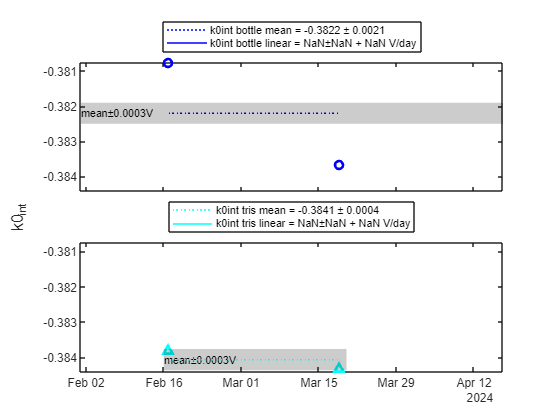


if k2int_opt == "other"
    disp(k2int_other)
end

if isempty(bott)==0
% discrete bottle k0
    TC = bottqc.TCINSITU;
    Vint = bottqc.VINT;
    pHcal = bottqc.PHINSITU;
    % Univ gas constant, Faraday constant, 
    R = 8.31451; F = 96487; 
    % Temperature dependence of standard potentials, Martz et al. 2010
    %k2int = -0.001455; k2ext = -0.001048;
    % See Martz et al. 2010 for greater detail
    TK = TC+273.15; % Convert temp from C to K
    S_T = (R*TK)./F*log(10); % Nernst temp dependence
    k0int_insitu = Vint-S_T.*pHcal; % Calc E0int from Nernst & pH @ calibration point
    k0int = k0int_insitu-k2int.*(TC);
    bottqc.K0INT = k0int;
else
    bottqc.PHINSITU = NaN;
end

% tris k0
TC = trisqc.TCINSITU;
Vint = trisqc.VINT;
pHcal = trisqc.PHINSITU;
% Univ gas constant, Faraday constant, 
R = 8.31451; F = 96487; 
% Temperature dependence of standard potentials, Martz et al. 2010
%k2int = -0.001455; k2ext = -0.001048;
% See Martz et al. 2010 for greater detail
TK = TC+273.15; % Convert temp from C to K
S_T = (R*TK)./F*log(10); % Nernst temp dependence
k0int_insitu = Vint-S_T.*pHcal; % Calc E0int from Nernst & pH @ calibration point
k0int = k0int_insitu-k2int.*(TC);
trisqc.K0INT = k0int;

% bottle linear fit
if isempty(bott)==0
dt = days(bottqc.DTUTC-bottqc.DTUTC(1));
if length(bottqc.DTUTC) > 2 % do fitlm if more than 2 samples
    %pintdisc = polyfit(days(dt),bott.k0int,1);
    %pintdiscval = polyval(pintdisc,days(raw.DTUTC-raw.DTUTC(1)));
    bmdl = fitlm(dt, bottqc.K0INT);
    bcoef = coefCI(bmdl);
    bci = std(bcoef(1,:));
else
    %pintdiscval = ones(length(raw.DTUTC),1)*mean(bott.k0int,'omitmissing');
    bmdl = table();
    bmdl.Fitted = NaN;
    bcoef = [NaN; NaN];
    bci = NaN;
end
else
    bottqc.DTUTC = NaT;
    bottqc.K0INT = NaN;
    bmdl = table();
    bmdl.Fitted = NaN;
    bcoef = [NaN; NaN];
    bci = NaN;
end


% tris linear fit
if isempty(trisqc)==0
    dt = days(trisqc.DTUTC-trisqc.DTUTC(1));
    if length(trisqc.DTUTC) > 2
        %pinttris = polyfit(days(dt),tris.k0int,1);
        %pinttrisval = polyval(pinttris,days(raw.DTUTC-raw.DTUTC(1)));    
        tmdl = fitlm(dt, trisqc.K0INT,'RobustOpts','on');
        tcoef = coefCI(tmdl);
        tci = std(tcoef(1,:));
    else
        %pinttrisval = ones(length(raw.DTUTC),1)*mean(tris.k0int,'omitmissing');
        tmdl = table();
        tmdl.Fitted = NaN;
        tcoef = [NaN;NaN];
        tci = NaN;
    end
else
    tmdl = table();
    tmdl.Fitted = NaN;
    tci = NaN;
end

% k0 stats for plotting
if isempty(bott)==0
mb = mean(bottqc.K0INT,'omitmissing'); 
sb = std(bottqc.K0INT,'omitmissing');
else
    mb = NaN;
    sb = NaN;
end
mt = mean(trisqc.K0INT,'omitmissing'); st = std(trisqc.K0INT,'omitmissing');

% plot k0
k0fig = figure;
tl = tiledlayout(2,1,'TileSpacing', 'tight');

ax1 = nexttile;
if isempty(bott)==0
    plot(bottqc.DTUTC, bottqc.K0INT,'bo',LineWidth=2); hold on
    
    if length(bottqc.DTUTC)>2 % linear fit
        plot(bottqc.DTUTC, bmdl.Fitted,'b-');
        X = [bottqc.DTUTC(1) bottqc.DTUTC(end) bottqc.DTUTC(end) bottqc.DTUTC(1)];
        y = [bmdl.Fitted(1)-bci bmdl.Fitted(end)-bci bmdl.Fitted(end)+bci bmdl.Fitted(1)+bci];
        patch(X,y,'blue','EdgeColor','None','FaceAlpha',0.2)
    else % mean
        plot(bottqc.DTUTC, [mb mb],'b:'); hold on
        % X = [bott.DTUTC(1) bott.DTUTC(end) bott.DTUTC(end) bott.DTUTC(1)];
        % y = [mb-sb mb-sb mb+sb mb+sb];
        % patch(X,y,'blue','EdgeColor','None','FaceAlpha',0.2)
    end
else
    plot(NaT,NaN);
end

ylabel(tl,'k0_{int}');
ax1.XTickLabel = '';
xlim([data.DTUTC(1) data.DTUTC(end)])
b.XData = [ax1.XLim(1) ax1.XLim(2) ax1.XLim(2) ax1.XLim(1)];
b.YData = [mb-0.0003 mb-0.0003 mb+0.0003 mb+0.0003];
b.FaceColor = 'k';
b.FaceAlpha = 0.2;
b.EdgeColor = 'none';
patch(b)
text(ax1.XLim(1),mb,"mean"+char(177)+"0.0003V",'FontSize',8)
%q{1} = patch(nan,nan,'black','FaceAlpha',0.2,'EdgeColor','none');
q{1} = plot(NaT,NaN,'b:');
q{2} = plot(NaT,NaN,'b-');
if isempty(bott)==0
legend([q{:}],{"k0int bottle mean = "+num2str(mb,'%.4f')+...
    " "+char(177)+" "+num2str(sb,'%.4f');
    "k0int bottle linear = "+num2str(mean(bcoef(1,:)),'%.4f')+char(177)+...
    num2str(bci,'%.4f')+...
    " + "+num2str(mean(bcoef(2,:)),'%.2e')+" V/day"},...
    'Location','northoutside');
end

ax2 = nexttile;
plot(trisqc.DTUTC, trisqc.K0INT,'c^',LineWidth=2); hold on

b.XData = [ax2.XLim(1) ax2.XLim(2) ax2.XLim(2) ax2.XLim(1)];
b.YData = [mt-0.0003 mt-0.0003 mt+0.0003 mt+0.0003];
b.FaceColor = 'k';
b.FaceAlpha = 0.2;
b.EdgeColor = 'none';
patch(b)
text(ax2.XLim(1),mt,"mean"+char(177)+"0.0003V",'FontSize',8)
if length(trisqc.DTUTC)>2 % linear fit
    plot(trisqc.DTUTC, tmdl.Fitted,'c-');
    X = [trisqc.DTUTC(1) trisqc.DTUTC(end) trisqc.DTUTC(end) trisqc.DTUTC(1)];
    y = [tmdl.Fitted(1)-tci tmdl.Fitted(end)-tci tmdl.Fitted(end)+tci tmdl.Fitted(1)+tci];
    patch(X,y,'cyan','EdgeColor','None','FaceAlpha',0.2)
else % mean
    plot(trisqc.DTUTC, [mt mt],'c:'); hold on
    % X = [bott.DTUTC(1) bott.DTUTC(end) bott.DTUTC(end) bott.DTUTC(1)];
    % y = [mb-sb mb-sb mb+sb mb+sb];
    % patch(X,y,'blue','EdgeColor','None','FaceAlpha',0.2)
end


%q{1} = patch(nan,nan,'black','FaceAlpha',0.2,'EdgeColor','none');
q{1} = plot(nan,'c:');
q{2} = plot(nan,'c-');
legend([q{:}],{"k0int tris mean = "+num2str(mt,'%.4f')+...
    " "+char(177)+" "+num2str(st,'%.4f'); ...
    "k0int tris linear = "+num2str(mean(tcoef(1,:)),'%.4f')+char(177)+...
    num2str(tci,'%.4f')+...
    " + "+num2str(mean(tcoef(2,:)),'%.2e')+" V/day"},...
    'Location','northoutside');
if isempty(bott)==0
ax1.YLim = [min([ax1.YLim ax2.YLim]) max([ax1.YLim ax2.YLim])];
ax2.YLim = ax1.YLim;
ax2.XLim = ax1.XLim;
end

## Step 4: Calculate corrected pH using k0

Choose k0 option to use or enter a value for each coefficient (default values shown):

close all
k0int_opt = "tris mean"; k0int_constant = -0.4;
disp("k0int option used: "+k0int_opt)

k0int option used: tris mean


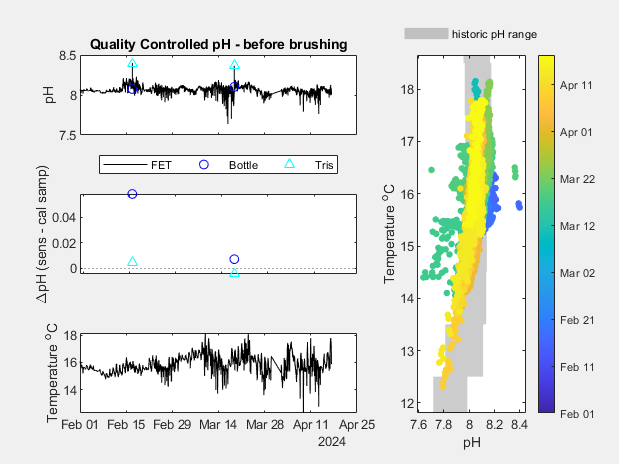

 
%it = 1; % iteration for brushing/replotting

% bottle mean
k0BOTTMEAN = mean(bottqc.K0INT,'omitmissing');

% bottle fit
d = days(data.DTUTC-bottqc.DTUTC(1));
k0BOTTFIT = bmdl.Fitted(1)+mean(bcoef(2,:))*d;

% tris mean
k0TRISMEAN = mean(trisqc.K0INT,'omitmissing');

% tris fit
d = days(data.DTUTC-trisqc.DTUTC(1));
k0TRISFIT = tmdl.Fitted(1)+mean(tcoef(2,:))*d;

if k0int_opt == "bottle mean"
    k0int = k0BOTTMEAN;
elseif k0int_opt == "bottle linear fit"
    k0int = k0BOTTFIT;
elseif k0int_opt == "tris mean"
    k0int = k0TRISMEAN;
elseif k0int_opt == "tris linear fit"
    k0int = k0TRISFIT;
else
    k0int = k0int_constant;
end

Vint = Vint_brushed;

TC = data.TEMPC;

% calculate corrected pH
% Univ gas constant, Faraday constant, 
R = 8.31451; F = 96487; 
% Temperature dependence of standard potentials, Martz et al. 2010
%k2int = -0.00125; k2ext = -0.001048;

tempK = TC+273.15; % Convert temp from C to K
S_T = (R*tempK)/F*log(10); % Nernst temp dependence
data.PHINT = (Vint-(k0int+k2int.*(TC)))./S_T; % Calc pHint from Nernst

bottqc.PHINT = interp1(data.DTUTC,data.PHINT,bottqc.DTUTC,'nearest');
trisqc.PHINT = interp1(data.DTUTC,data.PHINT,trisqc.DTUTC,'nearest');

pHfig = figure('name','pHfig');
set(pHfig,'Visible','on');
tiledlayout(3,3,'TileSpacing','tight');

ax1 = nexttile([1,2]);
plot(data.DTUTC, data.PHINT,'k-'); hold on
plot(bottqc.DTUTC, bottqc.PHINSITU, 'bo'); 
plot(trisqc.DTUTC, trisqc.PHINSITU, 'c^'); 
title('Quality Controlled pH - before brushing');
ylabel('pH');
ax1.XTickLabel = []; 
legend('FET','Bottle','Tris','Location','southoutside','Orientation','horizontal')

ax2 = nexttile([1,2]);
plot(bottqc.DTUTC, bottqc.PHINT - bottqc.PHINSITU,'bo'); hold on
plot(trisqc.DTUTC, trisqc.PHINT - trisqc.PHINSITU,'c^');
yline(0,'k:');
ylabel('\DeltapH (sens - cal samp)');
ax2.XTickLabel = [];

ax3 = nexttile([1,2]);
plot(data.DTUTC, data.TEMPC, 'k-'); hold on
ylabel('Temperature ^oC')

linkaxes([ax1 ax2 ax3],'x');

ax4 = nexttile([3,1]);
tc = 11:1:26;
m = [7.81; 7.85; 7.96; 8.03; 8.05; 8.06; 8.06; 8.07; 8.06; 8.07; 8.07; 8.08; 8.08; 8.10; 8.12; 8.16];
st = [0.06; 0.09; 0.10; 0.07; 0.06; 0.06; 0.06; 0.07; 0.07; 0.08; 0.08; 0.06; 0.07; 0.09; 0.08; 0.06];
for i = 1:length(tc)
    h = rectangle('Position',[m(i)-st(i)*3/2 tc(i)-0.5 st(i)*3 1],...
        'FaceColor',[0 0 0 0.2],'EdgeColor','none'); hold on
end
yl = [min(data.TEMPC)-.5 max(data.TEMPC)+.5];
ylim(yl)
xl = [min(data.PHINT)-.05 max(data.PHINT)+.05];
xlim(xl);
s = scatter(data.PHINT, data.TEMPC, 20, days(data.DTUTC-data.DTUTC(1)), 'filled');
s.DataTipTemplate.DataTipRows(3).Label = "date";
s.DataTipTemplate.DataTipRows(3).Value = string(data.DTUTC);
ylabel("Temperature ^oC")
xlabel("pH")
box on
cb = colorbar;
cb.TickLabels = string(data.DTUTC(1)+days(cb.Ticks), 'MMM dd');
f = plot(nan,'-','LineWidth',10,'Color',[0 0 0 0.2]);
l = legend(f,'historic pH range');
l.Box = "off";
l.Location = 'northoutside';

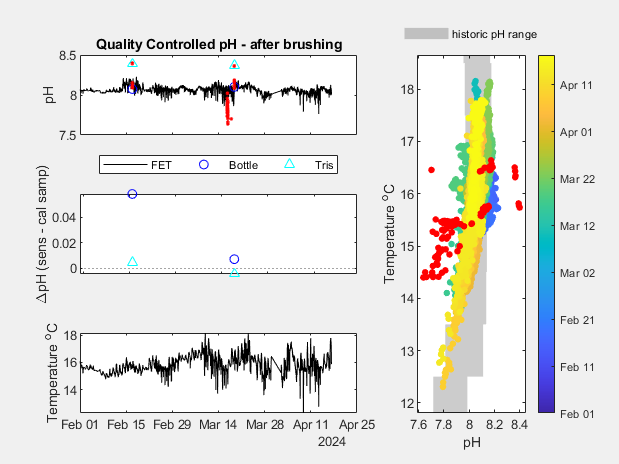

 

%if it == 1 % do only once unless data is rebrushed above
if isempty(findobj('type','figure','name','pHfig'))
    % do nothing
else
    set(pHfig,'Visible','off');
    pHint_brushed = ax1.Children(end).YData'; % has nans
    pHint_prebrushed = data.PHINT; % no nans
    data.PHINTCOR = pHint_brushed;
end
    
    
%end
it = 2;

% remove tris injections + 1 hour after
if all(isnan(tris.QC))
    % do nothing
else
    for i=1:length(tris.DTUTC)
        [val,idx] = min(abs(data.DTUTC-tris.DTUTC(i)));
        nid = data.DTUTC >= data.DTUTC(idx) & data.DTUTC <= data.DTUTC(idx)+hours(1);
        data.PHINTCOR(nid) = NaN;
    end
end

intnan = isnan(data.PHINTCOR); % indexes of nans to color red

pHfig = figure('name','pHfig');
set(pHfig,'Visible','on');
tiledlayout(3,3,'TileSpacing','tight');

ax1 = nexttile([1 2]);
plot(data.DTUTC, data.PHINTCOR,'k-'); hold on
plot(bottqc.DTUTC, bottqc.PHINSITU, 'bo'); hold on
plot(trisqc.DTUTC, trisqc.PHINSITU, 'c^');
plot(data.DTUTC(intnan),pHint_prebrushed(intnan),'r.'); hold on
title('Quality Controlled pH - after brushing')
ylabel('pH')
ax1.XTickLabel = [];
legend('FET','Bottle','Tris','Location','southoutside','Orientation','horizontal')

ax2 = nexttile([1 2]);
plot(bottqc.DTUTC, bottqc.PHINT - bottqc.PHINSITU,'bo'); hold on
plot(trisqc.DTUTC, trisqc.PHINT - trisqc.PHINSITU,'c^'); hold on
yline(0,'k:')
ylabel('\DeltapH (sens - cal samp)')
ax2.XTickLabel = [];


ax3 = nexttile([1,2]);
plot(data.DTUTC, data.TEMPC, 'k-'); hold on
ylabel('Temperature ^oC')

linkaxes([ax1 ax2 ax3],'x');

ax4 = nexttile([3,1]);
for i = 1:length(tc)
    h = rectangle('Position',[m(i)-st(i)*3/2 tc(i)-0.5 st(i)*3 1],...
        'FaceColor',[0 0 0 0.2],'EdgeColor','none'); hold on
end
ylim(yl);
xlim(xl);
s = scatter(data.PHINTCOR, data.TEMPC, 20, days(data.DTUTC-data.DTUTC(1)), 'filled'); hold on
s2 = scatter(pHint_prebrushed(intnan), data.TEMPC(intnan), 20, 'r', 'filled'); 
s.DataTipTemplate.DataTipRows(3).Label = "date";
s.DataTipTemplate.DataTipRows(3).Value = string(data.DTUTC);
s2.DataTipTemplate.DataTipRows(3).Label = "date";
s2.DataTipTemplate.DataTipRows(3).Value = string(data.DTUTC);
ylabel("Temperature ^oC")
xlabel("pH")
box on
cb = colorbar;
cb.TickLabels = string(data.DTUTC(1)+days(cb.Ticks), 'MMM dd');
f = plot(nan,'-','LineWidth',10,'Color',[0 0 0 0.2]);
l = legend(f,'historic pH range');
l.Box = "off";
l.Location = 'northoutside';

## Final notes and export

Enter QC notes here:

*******************************************************************************************

Operator: TW

Data gap Apr 1-2 due to cable issues and deployment being restarted. Sensor did not leave the water.

Removed all tris samples exept for last reading.

Tris mean k0, only 2 injections,  std just > 0.0003 V.

Potential for bottle samples to be during biofouling.

Negligable change removing initial tris readings. Removed last of injections due to outliers/cell might have been opened.

*******************************************************************************************

if isempty(findobj('type','figure','name','pHfig'))
    % do nothing
else
    set(pHfig,'Visible','off');
end

final = data;
final.QC = ones(length(final.PHINT),1);
final.QC(isnan(data.PHINTCOR)) = 2;
final = removevars(final,'PHINTCOR');
f = renamevars(final,'PHINT','PH');
f.K2 = ones(length(f.PH),1).*k2int;
f.K0USED = ones(length(f.PH),1).*k0int;
f.K0BOTTMEAN = ones(length(f.PH),1).*k0BOTTMEAN;
f.K0BOTTFIT = ones(length(f.PH),1).*k0BOTTFIT;
f.K0TRISMEAN = ones(length(f.PH),1).*k0TRISMEAN;
f.K0TRISFIT = ones(length(f.PH),1).*k0TRISFIT;


final_loc = "G:\Shared drives\FET_processing_GUI\SOAR_pH_processing_GUI_Matlab\SOAR_QC_mlx";
[filepath,name,ext] = fileparts(seafet_file);
filename2save = name+"_QC_"+string(datetime('now','TimeZone','UTC'),'uuuuMMddHHmmss');

save(final_loc+"\"+filename2save+".mat","f","-mat");


writetable(f,final_loc+"\"+filename2save+".csv","Delimiter",",","WriteMode","overwrite");

exp_pdf = export("SOAR_QC_live_script.mlx",final_loc+"\"+filename2save+".pdf",HideCode=true);

save(final_loc+"\Bottle_"+filename2save+".mat","bott","-mat");
writetable(bott,final_loc+"\Bottle_"+filename2save+".csv","Delimiter",",","WriteMode","overwrite");
save(final_loc+"\Tris_"+filename2save+".mat","tris","-mat");
writetable(tris,final_loc+"\Tris_"+filename2save+".csv","Delimiter",",","WriteMode","overwrite");

 
